clc;
close all;

## Create a FIS object using Mamdani Approach:

%Define a FIS object using the Mamdani Method
my_FIS= mamfis('Name', 'Marriage Decision Maker', ...
        'NumInputs',12, 'NumInputMFs', 3, ...
        'NumOutputs', 1, 'NumOutputMFs', 5, ...
        'AddRule', 'none');

    

## Define Input variables and MFs:

%Define the Input(1)
my_FIS.Inputs(1).Name= 'Age';
my_FIS.Inputs(1).Range= [10 50];
my_FIS.Inputs(1).MembershipFunctions(1).Name= 'Under_Age';
my_FIS.Inputs(1).MembershipFunctions(1).Type= 'trapmf';
my_FIS.Inputs(1).MembershipFunctions(1).Parameters= [10 12 14 18];
my_FIS.Inputs(1).MembershipFunctions(2).Name= 'Young';
my_FIS.Inputs(1).MembershipFunctions(2).Type= 'trapmf';
my_FIS.Inputs(1).MembershipFunctions(2).Parameters= [17 23 28 33];
my_FIS.Inputs(1).MembershipFunctions(3).Name= 'Old';
my_FIS.Inputs(1).MembershipFunctions(3).Type= 'trapmf';
my_FIS.Inputs(1).MembershipFunctions(3).Parameters= [30 35 50 50];


%Define the Input(2)
my_FIS.Inputs(2).Name= 'Height';
my_FIS.Inputs(2).Range= [122 213];
my_FIS.Inputs(2).MembershipFunctions(1).Name= 'Short';
my_FIS.Inputs(2).MembershipFunctions(1).Type= 'trapmf';
my_FIS.Inputs(2).MembershipFunctions(1).Parameters= [122 130 140 160];
my_FIS.Inputs(2).MembershipFunctions(2).Name= 'Medium';
my_FIS.Inputs(2).MembershipFunctions(2).Type= 'trapmf';
my_FIS.Inputs(2).MembershipFunctions(2).Parameters= [155 158 170 175];
my_FIS.Inputs(2).MembershipFunctions(3).Name= 'Tall';
my_FIS.Inputs(2).MembershipFunctions(3).Type= 'trapmf';
my_FIS.Inputs(2).MembershipFunctions(3).Parameters= [170 172 213 213];


%Define the Input(3)
my_FIS.Inputs(3).Name= 'Weight';
my_FIS.Inputs(3).Range= [40 150];
my_FIS.Inputs(3).MembershipFunctions(1).Name= 'Under_Weight';
my_FIS.Inputs(3).MembershipFunctions(1).Type= 'trapmf';
my_FIS.Inputs(3).MembershipFunctions(1).Parameters= [40 43 47 52];
my_FIS.Inputs(3).MembershipFunctions(2).Name= 'Normal_Weight';
my_FIS.Inputs(3).MembershipFunctions(2).Type= 'trapmf';
my_FIS.Inputs(3).MembershipFunctions(2).Parameters= [50 60 70 78];
my_FIS.Inputs(3).MembershipFunctions(3).Name= 'Obese';
my_FIS.Inputs(3).MembershipFunctions(3).Type= 'trapmf';
my_FIS.Inputs(3).MembershipFunctions(3).Parameters= [75 100 150 150];


%Define the Input(4)
my_FIS.Inputs(4).Name= 'Financial_Status';
my_FIS.Inputs(4).Range= [6000 200000];
my_FIS.Inputs(4).MembershipFunctions(1).Name= 'Lower_Class';
my_FIS.Inputs(4).MembershipFunctions(1).Type= 'gaussmf';
my_FIS.Inputs(4).MembershipFunctions(1).Parameters= [10000 20000];
my_FIS.Inputs(4).MembershipFunctions(2).Name= 'Middle_Class';
my_FIS.Inputs(4).MembershipFunctions(2).Type= 'gaussmf';
my_FIS.Inputs(4).MembershipFunctions(2).Parameters= [20000 70000];
my_FIS.Inputs(4).MembershipFunctions(3).Name= 'Elite_Class';
my_FIS.Inputs(4).MembershipFunctions(3).Type= 'gaussmf';
my_FIS.Inputs(4).MembershipFunctions(3).Parameters= [30000 150000];


%Define the Input(5) -- 4 MF
my_FIS.Inputs(5).Name= 'Originality';
my_FIS.Inputs(5).Range= [0 1];
my_FIS.Inputs(5).MembershipFunctions(1).Name= 'American';
my_FIS.Inputs(5).MembershipFunctions(1).Type= 'gaussmf';
my_FIS.Inputs(5).MembershipFunctions(1).Parameters= [0.05 0.2];
my_FIS.Inputs(5).MembershipFunctions(2).Name= 'Asian';
my_FIS.Inputs(5).MembershipFunctions(2).Type= 'gaussmf';
my_FIS.Inputs(5).MembershipFunctions(2).Parameters= [0.05 0.5];
my_FIS.Inputs(5).MembershipFunctions(3).Name= 'Arab';
my_FIS.Inputs(5).MembershipFunctions(3).Type= 'gaussmf';
my_FIS.Inputs(5).MembershipFunctions(3).Parameters= [0.05 0.7];
my_FIS.Inputs(5).MembershipFunctions(4).Name= 'Other';
my_FIS.Inputs(5).MembershipFunctions(4).Type= 'gaussmf';
my_FIS.Inputs(5).MembershipFunctions(4).Parameters= [0.05 0.9];


%Define the Input(6)
my_FIS.Inputs(6).Name= 'Education_Level';
my_FIS.Inputs(6).Range= [0 1];
my_FIS.Inputs(6).MembershipFunctions(1).Name= 'Secondary_School';
my_FIS.Inputs(6).MembershipFunctions(1).Type= 'gaussmf';
my_FIS.Inputs(6).MembershipFunctions(1).Parameters= [0.1 0.2];
my_FIS.Inputs(6).MembershipFunctions(2).Name= 'College';
my_FIS.Inputs(6).MembershipFunctions(2).Type= 'gaussmf';
my_FIS.Inputs(6).MembershipFunctions(2).Parameters= [0.1 0.5];
my_FIS.Inputs(6).MembershipFunctions(3).Name= 'Masters';
my_FIS.Inputs(6).MembershipFunctions(3).Type= 'gaussmf';
my_FIS.Inputs(6).MembershipFunctions(3).Parameters= [0.1 0.8];

%Define the Input(7) -- 4 MF
my_FIS.Inputs(7).Name= 'Career';
my_FIS.Inputs(7).Range= [0 1];
my_FIS.Inputs(7).MembershipFunctions(1).Name= 'Arts';
my_FIS.Inputs(7).MembershipFunctions(1).Type= 'gaussmf';
my_FIS.Inputs(7).MembershipFunctions(1).Parameters= [0.1 0.2];
my_FIS.Inputs(7).MembershipFunctions(2).Name= 'Engineering';
my_FIS.Inputs(7).MembershipFunctions(2).Type= 'gaussmf';
my_FIS.Inputs(7).MembershipFunctions(2).Parameters= [0.1 0.5];
my_FIS.Inputs(7).MembershipFunctions(3).Name= 'Medical';
my_FIS.Inputs(7).MembershipFunctions(3).Type= 'gaussmf';
my_FIS.Inputs(7).MembershipFunctions(3).Parameters= [0.1 0.7];
my_FIS.Inputs(7).MembershipFunctions(4).Name= 'Other';
my_FIS.Inputs(7).MembershipFunctions(4).Type= 'gaussmf';
my_FIS.Inputs(7).MembershipFunctions(4).Parameters= [0.1 0.9];

%Define the Input(8)
my_FIS.Inputs(8).Name= 'Sexual_Orientation';
my_FIS.Inputs(8).Range= [0 1];
my_FIS.Inputs(8).MembershipFunctions(1).Name= 'Straight';
my_FIS.Inputs(8).MembershipFunctions(1).Type= 'gaussmf';
my_FIS.Inputs(8).MembershipFunctions(1).Parameters= [0.1 0.2];
my_FIS.Inputs(8).MembershipFunctions(2).Name= 'Gay';
my_FIS.Inputs(8).MembershipFunctions(2).Type= 'gaussmf';
my_FIS.Inputs(8).MembershipFunctions(2).Parameters= [0.1 0.5];
my_FIS.Inputs(8).MembershipFunctions(3).Name= 'Lesbian';
my_FIS.Inputs(8).MembershipFunctions(3).Type= 'gaussmf';
my_FIS.Inputs(8).MembershipFunctions(3).Parameters= [0.1 0.7];
my_FIS.Inputs(8).MembershipFunctions(4).Name= 'Other';
my_FIS.Inputs(8).MembershipFunctions(4).Type= 'gaussmf';
my_FIS.Inputs(8).MembershipFunctions(4).Parameters= [0.1 0.9];

%Define the Input(9)
my_FIS.Inputs(9).Name= 'Food';
my_FIS.Inputs(9).Range= [0 1];
my_FIS.Inputs(9).MembershipFunctions(1).Name= 'Veg';
my_FIS.Inputs(9).MembershipFunctions(1).Type= 'gaussmf';
my_FIS.Inputs(9).MembershipFunctions(1).Parameters= [0.1 0.2];
my_FIS.Inputs(9).MembershipFunctions(2).Name= 'Halal_Non_Veg';
my_FIS.Inputs(9).MembershipFunctions(2).Type= 'gaussmf';
my_FIS.Inputs(9).MembershipFunctions(2).Parameters= [0.1 0.5];
my_FIS.Inputs(9).MembershipFunctions(3).Name= 'Haram_Non_Veg';
my_FIS.Inputs(9).MembershipFunctions(3).Type= 'gaussmf';
my_FIS.Inputs(9).MembershipFunctions(3).Parameters= [0.1 0.7];
my_FIS.Inputs(9).MembershipFunctions(4).Name= 'Sea_Food';
my_FIS.Inputs(9).MembershipFunctions(4).Type= 'gaussmf';
my_FIS.Inputs(9).MembershipFunctions(4).Parameters= [0.1 0.9];


%Define the Input(10)
my_FIS.Inputs(10).Name= 'Horoscope';
my_FIS.Inputs(10).Range= [0 1];
my_FIS.Inputs(10).MembershipFunctions(1).Name= 'Cancer';
my_FIS.Inputs(10).MembershipFunctions(1).Type= 'gaussmf';
my_FIS.Inputs(10).MembershipFunctions(1).Parameters= [0.1 0.2];
my_FIS.Inputs(10).MembershipFunctions(2).Name= 'Scorpio';
my_FIS.Inputs(10).MembershipFunctions(2).Type= 'gaussmf';
my_FIS.Inputs(10).MembershipFunctions(2).Parameters= [0.1 0.4];
my_FIS.Inputs(10).MembershipFunctions(3).Name= 'Libra';
my_FIS.Inputs(10).MembershipFunctions(3).Type= 'gaussmf';
my_FIS.Inputs(10).MembershipFunctions(3).Parameters= [0.1 0.6];
my_FIS.Inputs(10).MembershipFunctions(4).Name= 'Virgo';
my_FIS.Inputs(10).MembershipFunctions(4).Type= 'gaussmf';
my_FIS.Inputs(10).MembershipFunctions(4).Parameters= [0.1 0.8];
my_FIS.Inputs(10).MembershipFunctions(5).Name= 'Other';
my_FIS.Inputs(10).MembershipFunctions(5).Type= 'gaussmf';
my_FIS.Inputs(10).MembershipFunctions(5).Parameters= [0.1 0.9];


%Define the Input(11)
my_FIS.Inputs(11).Name= 'Religion';
my_FIS.Inputs(11).Range= [0 1];
my_FIS.Inputs(11).MembershipFunctions(1).Name= 'Atheist';
my_FIS.Inputs(11).MembershipFunctions(1).Type= 'gaussmf';
my_FIS.Inputs(11).MembershipFunctions(1).Parameters= [0.1 0.2];
my_FIS.Inputs(11).MembershipFunctions(2).Name= 'Judaism';
my_FIS.Inputs(11).MembershipFunctions(2).Type= 'gaussmf';
my_FIS.Inputs(11).MembershipFunctions(2).Parameters= [0.1 0.4];
my_FIS.Inputs(11).MembershipFunctions(3).Name= 'Christianity';
my_FIS.Inputs(11).MembershipFunctions(3).Type= 'gaussmf';
my_FIS.Inputs(11).MembershipFunctions(3).Parameters= [0.1 0.6];
my_FIS.Inputs(11).MembershipFunctions(4).Name= 'Islam';
my_FIS.Inputs(11).MembershipFunctions(4).Type= 'gaussmf';
my_FIS.Inputs(11).MembershipFunctions(4).Parameters= [0.1 0.8];
my_FIS.Inputs(11).MembershipFunctions(5).Name= 'Other';
my_FIS.Inputs(11).MembershipFunctions(5).Type= 'gaussmf';
my_FIS.Inputs(11).MembershipFunctions(5).Parameters= [0.1 0.9];


%Define the Input(12)
my_FIS.Inputs(12).Name= 'Beauty';
my_FIS.Inputs(12).Range= [0 1];
my_FIS.Inputs(12).MembershipFunctions(1).Name= 'Ugly';
my_FIS.Inputs(12).MembershipFunctions(1).Type= 'gaussmf';
my_FIS.Inputs(12).MembershipFunctions(1).Parameters= [0.1 0.2];
my_FIS.Inputs(12).MembershipFunctions(2).Name= 'Fair';
my_FIS.Inputs(12).MembershipFunctions(2).Type= 'gaussmf';
my_FIS.Inputs(12).MembershipFunctions(2).Parameters= [0.1 0.4];
my_FIS.Inputs(12).MembershipFunctions(3).Name= 'Good_Looking';
my_FIS.Inputs(12).MembershipFunctions(3).Type= 'gaussmf';
my_FIS.Inputs(12).MembershipFunctions(3).Parameters= [0.1 0.6];
my_FIS.Inputs(12).MembershipFunctions(4).Name= 'Cute';
my_FIS.Inputs(12).MembershipFunctions(4).Type= 'gaussmf';
my_FIS.Inputs(12).MembershipFunctions(4).Parameters= [0.1 0.8];
my_FIS.Inputs(12).MembershipFunctions(5).Name= 'Attractive';
my_FIS.Inputs(12).MembershipFunctions(5).Type= 'gaussmf';
my_FIS.Inputs(12).MembershipFunctions(5).Parameters= [0.1 0.9];


## Define Output Variable and MF:


%Define the Output
my_FIS.Outputs(1).Name= 'Decision';
my_FIS.Outputs(1).Range= [0 1];
my_FIS.Outputs(1).MembershipFunctions(1).Name= 'Very_Poor_Match';
my_FIS.Outputs(1).MembershipFunctions(1).Type= 'trapmf';
my_FIS.Outputs(1).MembershipFunctions(1).Parameters= [0 0.1 0.15 0.2];
my_FIS.Outputs(1).MembershipFunctions(2).Name= 'Poor_Match';
my_FIS.Outputs(1).MembershipFunctions(2).Type= 'trapmf';
my_FIS.Outputs(1).MembershipFunctions(2).Parameters= [0.18 0.22 0.26 0.35];
my_FIS.Outputs(1).MembershipFunctions(3).Name= 'Decent_Match';
my_FIS.Outputs(1).MembershipFunctions(3).Type= 'trapmf';
my_FIS.Outputs(1).MembershipFunctions(3).Parameters= [0.32 0.40 0.45 0.55];
my_FIS.Outputs(1).MembershipFunctions(4).Name= 'Good_Match';
my_FIS.Outputs(1).MembershipFunctions(4).Type= 'trapmf';
my_FIS.Outputs(1).MembershipFunctions(4).Parameters= [0.50 0.60 0.65 0.75];
my_FIS.Outputs(1).MembershipFunctions(5).Name= 'Excellent_Match';
my_FIS.Outputs(1).MembershipFunctions(5).Type= 'trapmf';
my_FIS.Outputs(1).MembershipFunctions(5).Parameters= [0.70 0.80 0.90 1.0];


## Fuzzy Inference Engine (Define Rules)


%Inference Engine (Rules)
rules= ["If Age is Under_Age then Decision is Very_Poor_Match";
    "If Age is Young AND Height is NOT Short then Decision is Good_Match"; 
    "If Age is Young AND Financial_Status is NOT Lower_Class then Decision is Excellent_Match";
    "If Height is Short then Decision is Very_Poor_Match"; 
    "If Weight is Obese then Decision is Very_Poor_Match"; 
    "If Weight is Normal_Weight AND Height is Medium then Decision is Decent_Match"; 
    "If Weight is Normal_Weight AND Height is Tall then Decision is Excellent_Match"; 
    "If Originality is NOT Other AND Sexual_Orientation is Straight then Decision is Good_Match"; 
    "If Career is NOT Other AND Financial_Status is Elite_Class then Decision is Excellent_Match"; 
    "If Food is Halal_Non_Veg then Decision is Very_Poor_Match";
    "If Religion is NOT Other AND Food is Halal_Non_Veg then Decision is Decent_Match"; 
    "If Career is Medical AND Beauty is Good_Looking then Decision is Good_Match"; 
    "If Career is Medical AND Beauty is Cute then Decision is Excellent_Match"; 
    "If Sexual_Orientation is Other AND Financial_Status is NOT Elite_Class AND Height is NOT Short AND Religion is NOT Islam then Decision is Very_Poor_Match";
    "If Beauty is Attractive then Decision is Excellent_Match";
    "If Beauty is Ugly then Decision is Very_Poor_Match";
    "If Beauty is Fair then Decision is Decent_Match";
    "If Beauty is Good_Looking then Decision is Good_Match";
    "If Beauty is Cute then Decision is Excellent_Match";
    "If Beauty is Cute AND Career is NOT Other AND Weight is Normal_Weight AND Financial_Status is NOT Lower_Class AND Originality is Asian then Decision is Excellent_Match";
    "If Horoscope is NOT Other AND Beauty is NOT Ugly AND Sexual_Orientation is Straight THEN Decision is Decent_Match";
    "If Food is Haram_Non_Veg AND Religion is NOT Islam THEN Decision is Very_Poor_Match";
    "If Originality is Asian AND Horoscope is NOT Other AND Religion is NOT Atheist THEN Decision is Good_Match";
    "If Originality is Asian AND Horoscope is NOT Other AND Religion is NOT Atheist AND Beauty is Cute THEN Decision is Excellent_Match";
    "If Height is Short AND Weight is Obese AND Beauty is Ugly THEN Decision is Very_Poor_Match";
    "If Height is Medium AND Weight is Normal_Weight AND Beauty is Good_Looking THEN Decision is Good_Match";
    "If Height is Medium AND Weight is Normal_Weight AND Beauty is Attractive THEN Decision is Excellent_Match";
    ];

my_FIS= addRule(my_FIS,rules);


## Evaluate the System

x= [25,165,70,50000,0.5,0.6,0.7,0.5,0.2,0.2,0.1,0.8];
y= evalfis(my_FIS,x)

y = 0.6599

## Open in Fuzzy Logic Designer

%fuzzyLogicDesigner(my_FIS)

##  Read Tuned FIS and Add More Rules:

%Read tuned system
tuned_FIS= readfis("TunedModel.fis");

%add more rules
more_rules= ["If Education_Level is Secondary_School AND Age is Under_Age AND Beauty is Cute Then Decision is Decent_Match";
    "If Education_Level is College AND Age is Young AND Beauty is Cute Then Decision is Excellent_Match";
    "If Education_Level is College AND Weight is Normal_Weight AND Originality is Asian AND Career is Medical THEN Decision is Excellent_Match";
    ];

tuned_FIS= addRule(tuned_FIS, more_rules);


## Test Cases on Tuned System:

x1= [25 150 70 80000 0.5 0.4 0.4 0.3 0.1 0.3 0.7 1.0]; %Beautiful Looks Case
x2= [25 165 70 7000 0.5 0.6 0.7 0.5 0.2 0.2 0.1 0.4]; %Low Income Case
x3= [50 200 75 80000 0.5 0.5 0.6 0.8 0.4 0.2 0.1 0.2]; %Old age case
x4= [10 150 70 80000 0.5 0.1 0.4 0.3 0.1 0.3 0.7 0.5]; %under age case
x5= [25 123 70 80000 0.5 0.1 0.4 0.3 0.1 0.3 0.7 0.5]; %short height case

y1= evalfis(my_FIS,x1)

y1 = 0.5916

y2= evalfis(my_FIS,x2)

y2 = 0.6040

y3= evalfis(my_FIS,x3)

y3 = 0.4683

y4= evalfis(my_FIS,x4)

y4 = 0.4584

y5= evalfis(my_FIS,x5)

y5 = 0.6511

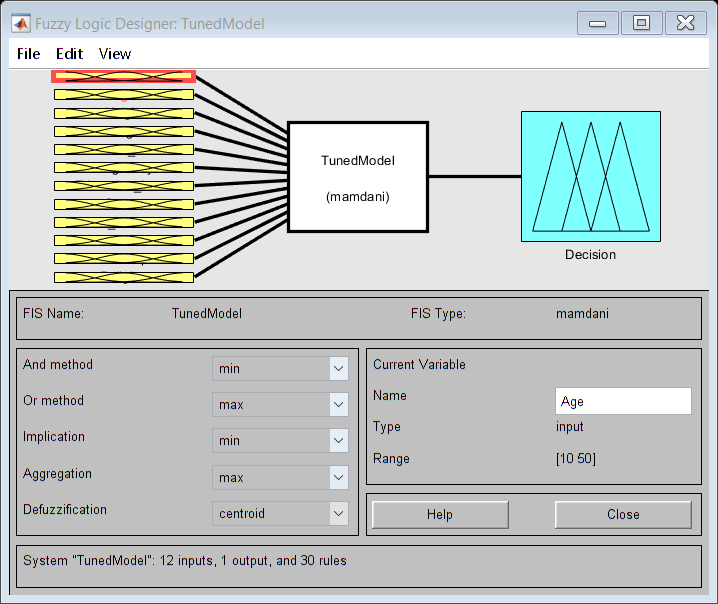

fuzzyLogicDesigner(tuned_FIS)